# Prácticas de Matlab

# Diagrama de eficiencia con métodos monopaso explícitos

# Hoja 3

**Nombre: Adrián**

**Apellido: Lattes**

**DNI: 50776040K**

## 1. Diagrama de eficiencia

### Práctica 1 (El método de Euler explícito) 

Consideramos el siguiente problema lineal


$$   y^{\prime}(t)=Ay(t)+B(t) \quad\mbox{para} \quad 0\leq t\leq 10,\quad  
y(0)=(2,3)^{T},$$



$$    A=\left(\begin{array}{cc}        -2 & 1\\        1 & -2      \end{array}\right)    
\qquad    B(t) =\left(\begin{array}{l}        2\sin(t)\\        2(\cos(t)-\sin(t)      
\end{array}\right)$$


La solución exacta es:


$$  y=2e^{-t}\left(\begin{array}{l}      1\\      1    \end{array}\right)  
+  \left(\begin{array}{l}      \sin(t)\\      \cos(t)    \end{array}\right)$$


Se pide lo siguiente

- Resuelve este sistema mediante el método de *Euler explícito,* almacena el máximo en valor absoluto de la diferencia entre la solución exacta y la solución numérica calculada.  **Indicación:** piensa qué norma vas a usar, dependiendo del tipo de salida (vector columna o vector fila) que haya producido tu algoritmo. Efectúa este cálculo para varias elecciones

- del paso $h_j$ con $j=0,\ldots,7$ siendo $h_0=0.1$, $h_j=\frac{h_0}{2^j}$. Almacena los diferentes valores de $h_i$ en un vector $h_{vect}$.

- del número de puntos $N$ siendo $N_0=100$, $N_i=2^{i}N_0$. Almacena los diferentes valores de $N_i$ en un vector $N_{vect}$.

- número de las evaluaciones totales $Ev_i$ que realiza cada algoritmo para cada valor de $h_i$. Almacena los valores en un vector $Ev_{vect}$.

- Almacena los distintos errores en un vector de nombre  **error_euler**

Además

- Dibuja, en una misma ventana, en escala logarítmica, el error almacenado en el apartado anterior frente al paso $h$,  $h_{vect}$ * Indicación:* usa el comando `loglog` en vez del comando `plot`.

- Repite en otra figura lo mismo pero dibujando el error frente al vector  $N_{vect}$ 

- Calcula la pendiente da la recta.

- Repite en otra figura lo mismo pero dibujando el error frente al vector  $Ev_{vect}$.

- Interpreta el resultado.

###  Práctica 2 (Euler mejorado) 

Repite el apartado anterior con el método de Euler mejorado 

### Práctica 3 (Euler modificado)

 Repite el apartado anterior con el método de Euler modificado

###  Práctica 4 (Runge-Kutta 4)

 Repite el apartado anterior con el método de Runge-Kutta de orden 4.

  **OJO:**  pon siempre el diagrama de eficiencia de Euler, Euler modificado, Euler mejorado y Runge Kutta 4 en una gráfica:

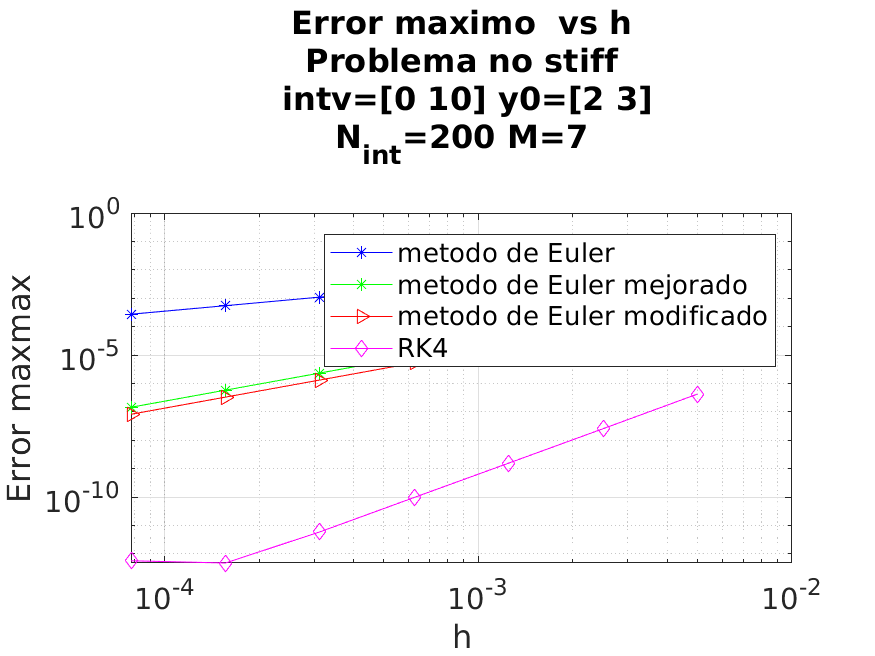

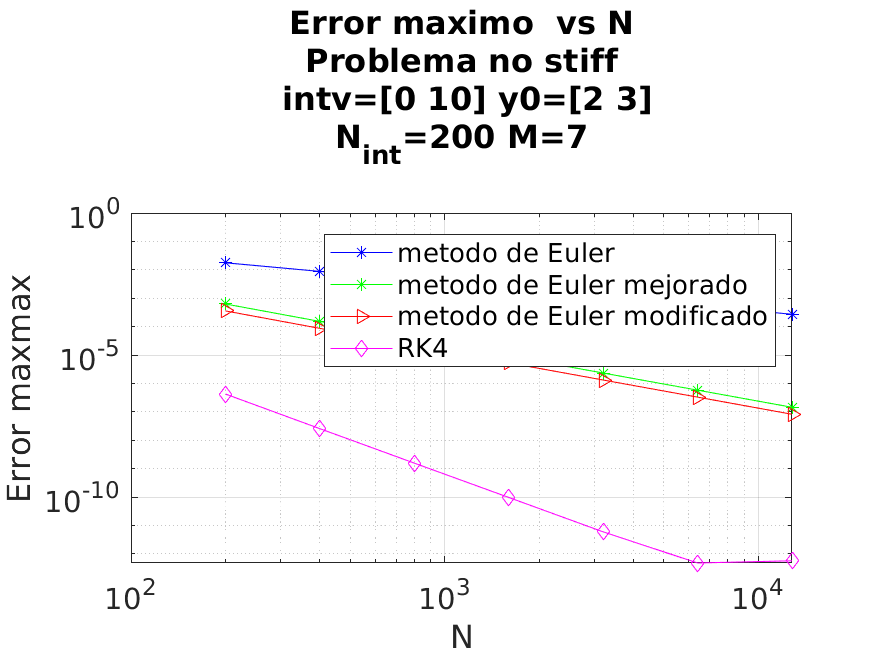

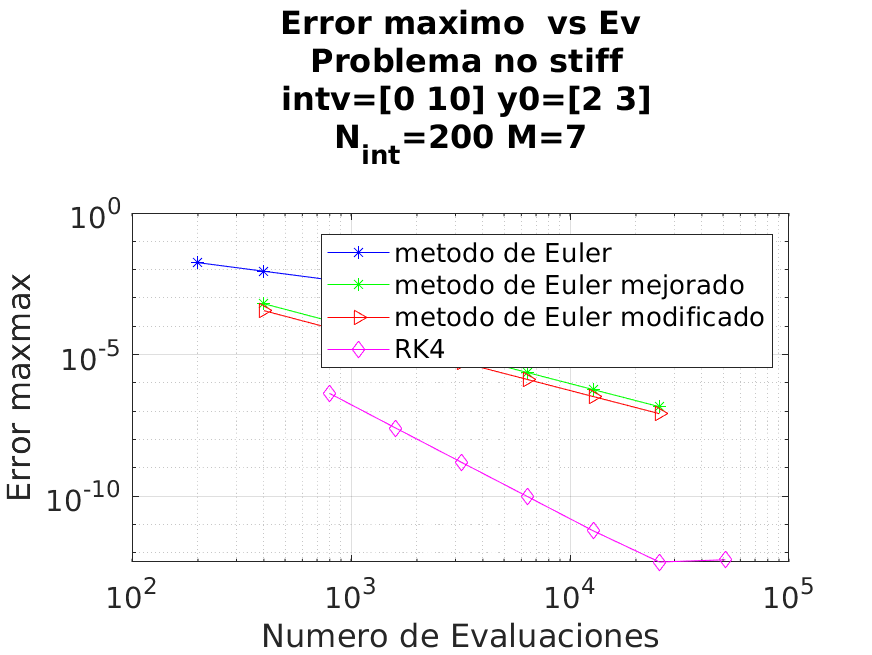

## Apéndice código: funciones de Euler, Euler modificado, Euler mejorado y Runge-Kutta 4, para calcular y pintar el diagrama de eficiencia y el orden

disp('Este es el código de Adrián (Hoja 3)')

Este es el código de Adrián (Hoja 3)


format long

global f intv y0 y;

% Definición del problema
f = @(t, y) [-2 1; 1 -2]*y + [2*sin(t); 2*(cos(t)-sin(t))];
intv = [0 10];
y0 = [2; 3];
y = @(t) 2*exp(-t).*[1; 1]+[sin(t); cos(t)]; %Solución exacta

nvect = 100.*2.^(0:7);
hvect = 0.1./(2.^(0:7));

disp("Calculando errores:")

Calculando errores:


disp("euler...")

euler...


errors_euler = errors(@mieuler,nvect);
disp("eulermej...")

eulermej...


errors_eulermej = errors(@mieulermej,nvect);
disp("eulermod...")

eulermod...


errors_eulermod = errors(@mieulermod,nvect);
disp("rk4...")

rk4...


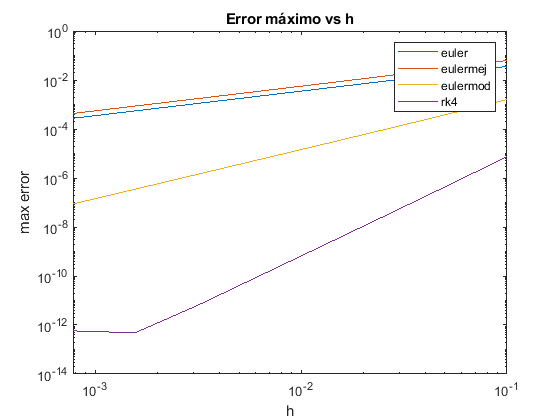

errors_mirk4 = errors(@mirk4,nvect);

% Diagrama 1: Max error vs h
figure(1)

loglog(hvect,errors_euler,hvect,errors_eulermej,hvect,errors_eulermod,hvect,errors_mirk4)
legend("euler","eulermej","eulermod","rk4")
title("Error máximo vs h")
xlabel("h")
ylabel("max error")

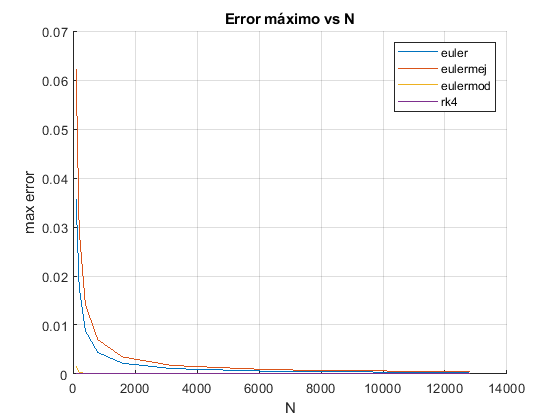



% Diagrama 2: Max error vs h
%subplot(1,3,2)
figure(2)
grid on
hold on
loglog(nvect,errors_euler,nvect,errors_eulermej,nvect,errors_eulermod,nvect,errors_mirk4)
legend("euler","eulermej","eulermod","rk4")
title("Error máximo vs N")
xlabel("N")
ylabel("max error")

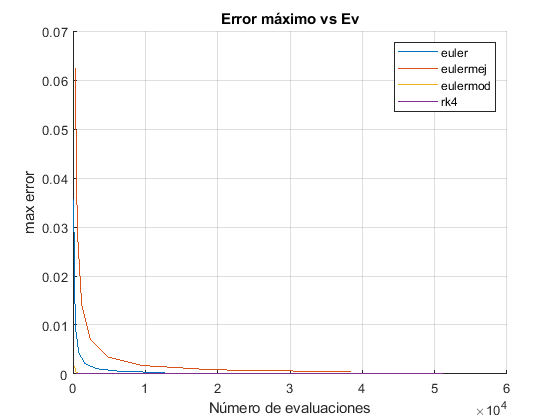



% Diagrama 3: Max error vs Ev
ev_euler = nvect;
ev_eulermej = nvect.*3;
ev_eulermod = nvect.*2;
ev_rk4 = nvect.*4;

figure(3)
%subplot(1,3,3)
grid on
hold on
loglog(ev_euler,errors_euler,ev_eulermej,errors_eulermej,ev_eulermod,errors_eulermod,ev_rk4,errors_mirk4)
legend("euler","eulermej","eulermod","rk4")
title("Error máximo vs Ev")
xlabel("Número de evaluaciones")
ylabel("max error")

function err = errors(met,nvect)
    global f intv y0 y;

    err=[];
    for i = 1:length(nvect)
        n = nvect(i);
        [t,ye] = met(f,intv,y0,n);
        maxnorm = max(max(abs(y(t)-ye)));
        err = [err maxnorm];
    end
end

function [t, y] = mieuler(f,intv,y0,N)
    t0 = intv(1);
    h = (intv(2)-t0)/N;
    t = t0;
    s = t;
    y = y0;
    w = y;
    for k = 1:N
        w = w + h*f(s,w);
        s = s + h;
        t = [t s];
        y = [y w];
    end
end

function [t, y] = mieulermej(f,intv,y0,N)
    t0 = intv(1);
    h = (intv(2)-t0)/N;
    t = t0;
    s = t;
    y = y0;
    w = y;
    for k = 1:N
        w = w + h/2*(f(s,w) + f(s,w + h*f(s,w)));
        s = s + h;
        t = [t s];
        y = [y w];
    end
end

function [t, y] = mieulermod(f,intv,y0,N)
    t0 = intv(1);
    h = (intv(2)-t0)/N;
    t = t0;
    s = t;
    y = y0;
    w = y;
    for k = 1:N
        w = w + h*f(s+h/2,w + h/2*f(s,w));
        s = s + h;
        t = [t s];
        y = [y w];
    end
end

function [t, y] = mirk4(f,intv,y0,N)
    t0 = intv(1);
    h = (intv(2)-t0)/N;
    t = t0;
    s = t;
    y = y0;
    w = y;
    for k = 1:N
        F1=f(s,w);
        F2=f(s+h/2,w+h/2*F1);
        F3=f(s+h/2,w+h/2*F2);
        F4=f(s+h,w+h*F3);
        w = w + h/6*(F1+2*F2+2*F3+F4);
        s = s + h;
        t = [t s];
        y = [y w];
    end
end


